syms t 

V(t) = [180*cosd(60); 180*sind(60) - 9.81 * t]

$$V(t) = \left(\begin{array}{c} 90\\ 90\,\sqrt{3}-\frac{981\,t}{100} \end{array}\right)$$


X(t) = int(V(t), t)

$$X(t) = \left(\begin{array}{c} 90\,t\\ -\frac{9\,t\,\left(109\,t-2000\,\sqrt{3}\right)}{200} \end{array}\right)$$



t0 = solve(180*sind(60) - 9.81 * t == 0, t)

$$t0 = \frac{1000\,\sqrt{3}}{109}$$


vpa(X(t0), 5)

$$ans = \left(\begin{array}{c} 1430.1\\ 1238.5 \end{array}\right)$$

xx = X(t0)

$$xx = \left(\begin{array}{c} \frac{90000\,\sqrt{3}}{109}\\ \frac{135000}{109} \end{array}\right)$$


solve(x == 90 * t, t)

$$ans = \frac{x}{90}$$


y(x) = subs(-(9*t*(109*t - 2000*sqrt(sym(3))))/200, t, x/90) %subs t = x/90 for at få en ligning af y(x)

$$y(x) = -\frac{x\,\left(\frac{109\,x}{90}-2000\,\sqrt{3}\right)}{2000}$$


y(x) = simplify(y(x))

$$y(x) = \sqrt{3}\,x-\frac{109\,x^{2}}{180000}$$


xt0 = xx(1)

$$xt0 = \frac{90000\,\sqrt{3}}{109}$$


vpa(y(xt0), 5)

$$ans = 1238.5$$

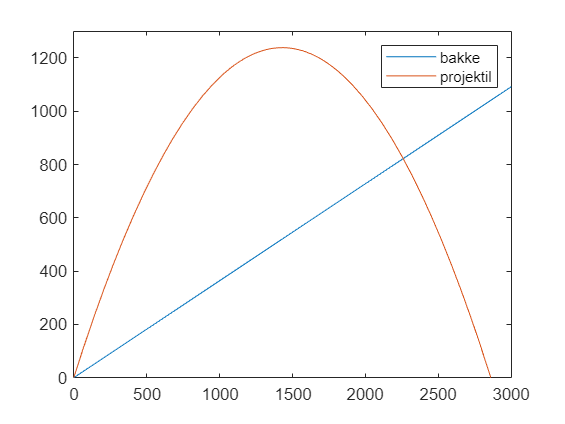

syms x
figure
fplot(tand(20)*x)
hold on
fplot(y(x))
legend(["bakke", "projektil"])
xlim([0 3000])
ylim([0 1300])
hold off


vpa(solve(tand(20)*x==y(x), x), 5)

$$ans = \left(\begin{array}{c} 0\\ 2259.2 \end{array}\right)$$

vpa(y(2259.2), 5)

$$ans = 822.3$$


vpa(sqrt(822.3^2+2259.2^2), 5)

$$ans = 2404.2$$